clc;
clear;
close all;

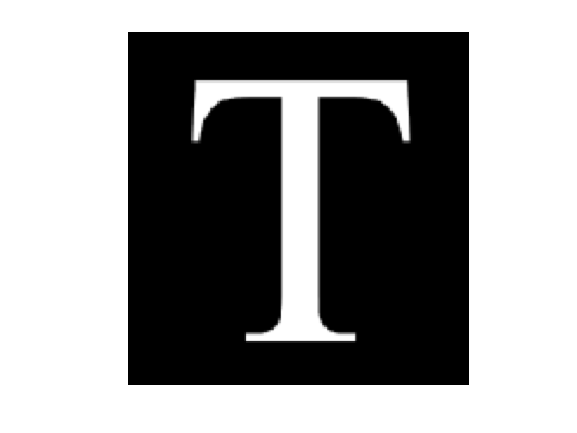

I = imread("imageT.png");
Im = rgb2gray(I);
imshow(Im);

Identidad

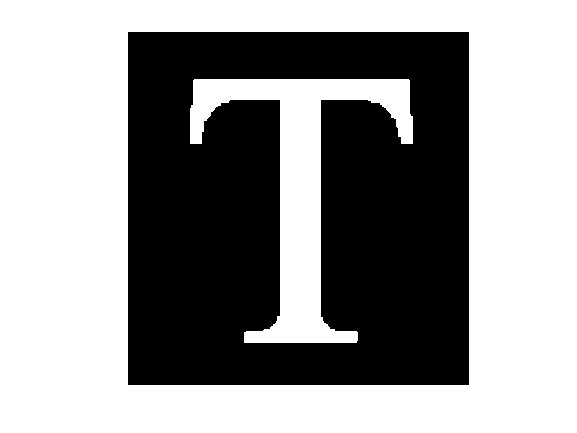

% [x, y] = size(Im);
% Im_identidad = zeros(x, y);
% M_identidad = [1 0 0; 0 1 0; 0 0 1];
% 
% for i=1:x
%     for j=1:y
%         xy = [i j 1] * M_identidad;
%         Im_identidad(xy(1), xy(2)) = Im(i,j);
%     end
% end
Im_identidad = identidad(Im);

imshow(Im_identidad);

Escalado

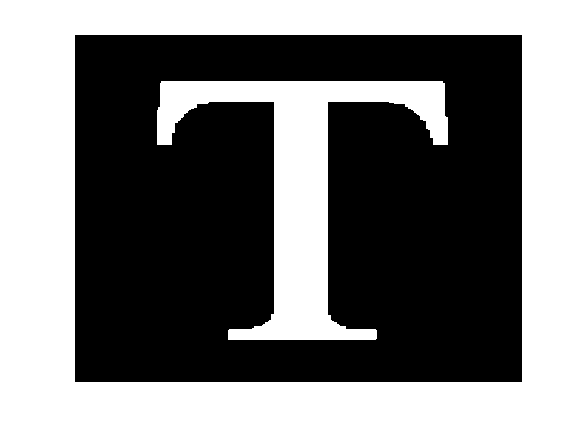

Cx = 3; Cy=4;
[x, y] = size(Im);
Img_Scalada = zeros(x*Cx, y*Cy);
M_escalada = [Cx 0 0; 0 Cy 0; 0 0 1];

for i=1:x
    for j=1:y
        xy = [i j 1] * M_escalada;
        Img_Scalada((xy(1)-Cx+1):xy(1), (xy(2)-Cy+1):xy(2)) = Im(i,j);
    end
end
imshow(Img_Scalada);

Rotacion

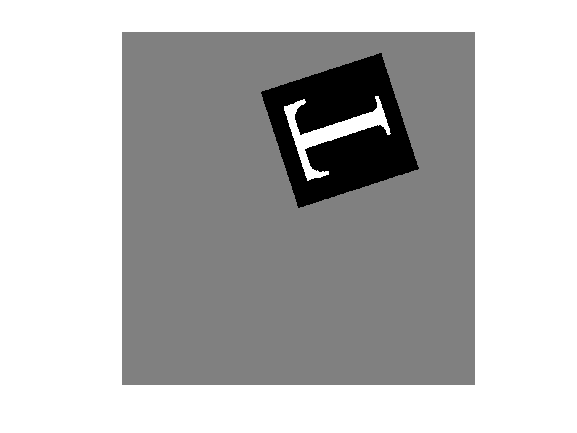

[x, y] = size(Im);
tam = 2*round((x^2+y^2)^0.5)+5;
tx = tam/2 ; ty = tam/2;
theta = 3*pi/5;
seno = sin(theta);
coseno = cos(theta);

Img_Rotacion = ones(tam, tam).*0.5;
M_rotacion = [coseno seno 0; -seno coseno 0; tx ty 1];
for i=1:x
    for j=1:y
        xy = ([i j 1] * M_rotacion);
        Img_Rotacion(round(xy(1)), round(xy(2)):round(xy(2))+1) = Im(i,j);
    end
end
imshow(Img_Rotacion);

desviacion horizontal

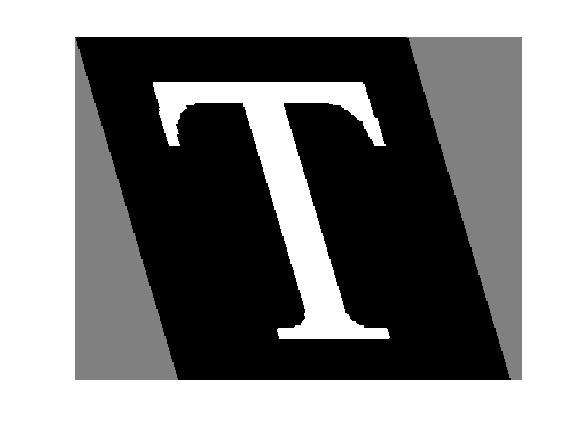

Sh=0.3;
[x, y] = size(Im);
Img_DesHorizon = ones(x, y+100).*0.5;
M_Horizontal = [1 Sh 0; 0 1 0; 0 0 1];

for i=1:x
    for j=1:y
        xy = [i j 1] * M_Horizontal;
        Img_DesHorizon(round(xy(1)), round(xy(2))) = Im(i,j);
    end
end
imshow(Img_DesHorizon);

desviacion vertical

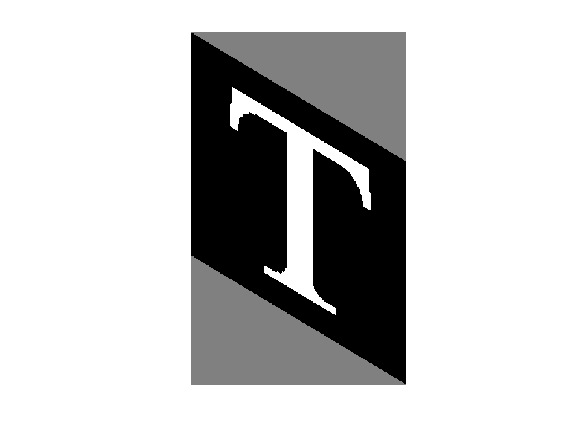

Sv=0.6;
[x, y] = size(Im);
Img_DesVert = ones(x+175, y).*0.5;
M_Vertical = [1 0 0; Sv 1 0; 0 0 1];

for i=1:x
    for j=1:y
        xy = [i j 1] * M_Vertical;
        Img_DesVert(round(xy(1)), round(xy(2))) = Im(i,j);
    end
end
imshow(Img_DesVert);

Traslacion

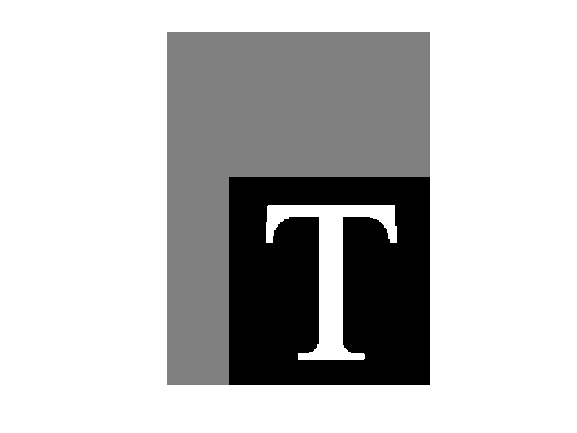

tx = 210 ; ty=90;
[x, y] = size(Im);
Img_Traslacion = ones(x+tx, y+ty).*0.5;
M_traslacion = [1 0 0; 0 1 0; tx ty 1];

for i=1:x
    for j=1:y
        xy = [i j 1] * M_traslacion;
        Img_Traslacion(xy(1), xy(2)) = Im(i,j);
    end
end
imshow(Img_Traslacion);

Corrección Gamma

I = imread("aerea.png")

I = 336×430×3 uint8 array
I(:,:,1) =

   204   204   205   206   204   204   204   204   204   204   204   204   204   204   204   204   205   208   209   209   209   210   210   210   211   212   212   212   212   212   211   211   211   211   211   211   211   211   211   211   211   211   211   213   214   214   214   214   214   214   214     3   214   214   214   214   214   219   219   219   219   219   219   219   219   219   219   219   219   219   216   216   216   216   216   216   216   216   216   216   216   216   218   221   221   221   221   221   221   221   221   221   221   221   221   221   220   220   220   220   220   220   220   220   220   220   220     3   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   223   223   223   223   223   223   223   223   223   223   223   223   224   225   225   225   225   225   225   225   225   225   225   225   225   228   228   229   229   229   229   229   229   229   229   229   229  

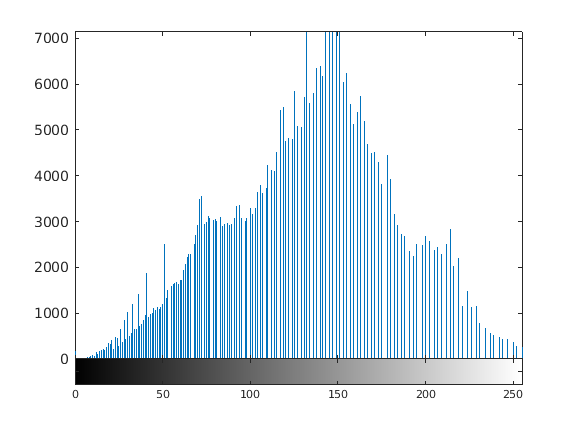

Correccion=im2uint8(mat2gray(double(I).^2.7));
%His = histeq(Correccion);
figure
imhist(Correccion)

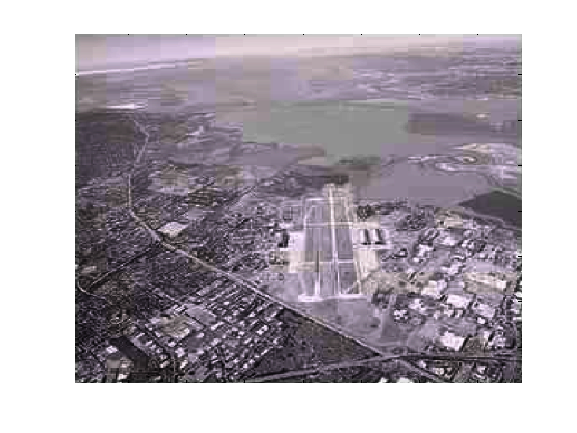

figure
imshow(Correccion);

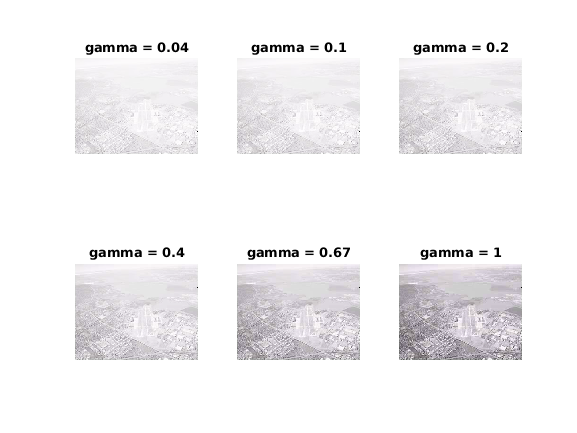

Correccion1=im2uint8(mat2gray(double(I).^0.04));
Correccion2=im2uint8(mat2gray(double(I).^0.1));
Correccion3=im2uint8(mat2gray(double(I).^0.2));
Correccion4=im2uint8(mat2gray(double(I).^0.4));
Correccion5=im2uint8(mat2gray(double(I).^0.67));
Correccion6=im2uint8(mat2gray(double(I).^1));
Correccion7=im2uint8(mat2gray(double(I).^1.5));
Correccion8=im2uint8(mat2gray(double(I).^2.5));
Correccion9=im2uint8(mat2gray(double(I).^5));
Correccion10=im2uint8(mat2gray(double(I).^10));
Correccion11=im2uint8(mat2gray(double(I).^10));

figure
subplot(2,3,1)
imshow(Correccion1); title("gamma = 0.04");
subplot(2,3,2)
imshow(Correccion2); title("gamma = 0.1");
subplot(2,3,3)
imshow(Correccion3); title("gamma = 0.2");
subplot(2,3,4)
imshow(Correccion4); title("gamma = 0.4");
subplot(2,3,5)
imshow(Correccion5); title("gamma = 0.67");
subplot(2,3,6)
imshow(Correccion6); title("gamma = 1");

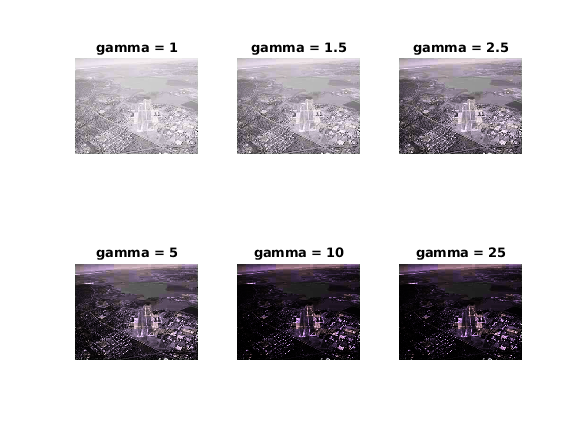

figure
subplot(2,3,1)
imshow(Correccion6); title("gamma = 1");
subplot(2,3,2)
imshow(Correccion7); title("gamma = 1.5");
subplot(2,3,3)
imshow(Correccion8); title("gamma = 2.5");
subplot(2,3,4)
imshow(Correccion9); title("gamma = 5");
subplot(2,3,5)
imshow(Correccion10); title("gamma = 10");
subplot(2,3,6)
imshow(Correccion11); title("gamma = 25");

histograma

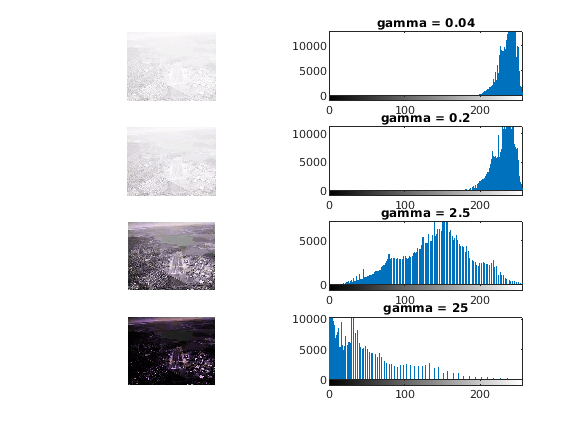

His1 = Correccion1;
His2 = Correccion3;
His3 = Correccion8;
His4 = Correccion11;
figure
subplot(4,2,1); imshow(Correccion1);
subplot(4,2,2); imhist(His1); title("gamma = 0.04");
subplot(4,2,3); imshow(Correccion3);
subplot(4,2,4); imhist(His2); title("gamma = 0.2");
subplot(4,2,5); imshow(Correccion8);
subplot(4,2,6); imhist(His3); title("gamma = 2.5");
subplot(4,2,7); imshow(Correccion11);
subplot(4,2,8); imhist(His4); title("gamma = 25");